# **Численные методы в СПб АУ РАН - Часть 2**

## **Задание по практике №8**

Кузьмичев Артём, 4 курс

## **№1 (алгоритмы и программы к разделу 10.3)**

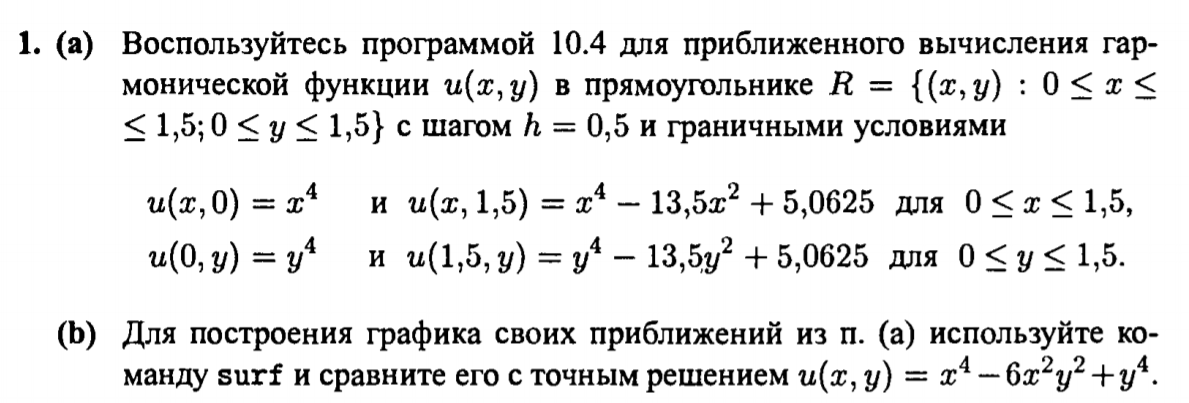

#### Постановка краевой задачи

Решаем $\Delta u\left(x,y\right)=0$ в области $\left\lbrack 0,a\right\rbrack \times \left\lbrack 0,b\right\rbrack$ с соответствующими граничными условиями

clear
syms x y f1(x) f2(x) f3(y) f4(y) U(x,y)

a = 1.5;
b = 1.5;

f1(x) = x^4;
f2(x) = x^4 - 13.5*x^2 + 5.0625;
f3(y) = y^4;
f4(y) = y^4 - 13.5*y^2 + 5.0625;

h=0.5;

tol= 1e-12; %погрешность
max1 = 1000; %максимальное число итераций внутри алгоритма

## Метод Дирихле для уравнения Лапласа:

Воспользуемся функцией, реализующей метод Дирихле для h = 0.5 

U = dirich(f1,f2,f3,f4,a,b,h,tol,max1)

required tolerance reached


U =     0.0625    0.0625    1.0000    5.0625
    0.0625   -0.1250   -0.3125    1.7500
    1.0000   -0.3125   -3.8750   -7.4375
    5.0625    1.7500   -7.4375  -20.2500


В действительности, предложенный в задаче шаг слишком большой, и не составит труда вычислить функцию с меньшим h:

hs=0.005;
Us = dirich(f1,f2,f3,f4,a,b,hs,tol,max1)

max iteration number reached


Us =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0016    0.0018    0.0019    0.0021    0.0023    0.0026    0.0028    0.0030    0.0033    0.0036
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0016    0.0018    0.0019    0.0021    0.0023    0.0026    0.0028    0.0030    0.0033    

Построим графики:

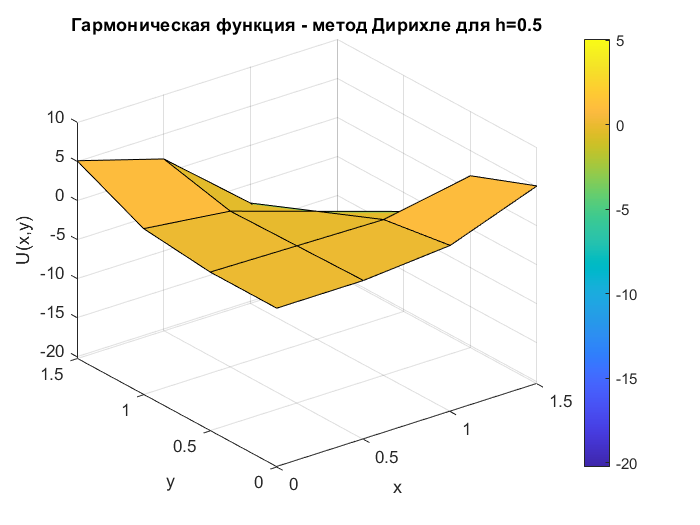

figure
X1 = 0:h:a;
Y1 = 0:h:b;
surf(X1,Y1,U)
colorbar
title('Гармоническая функция - метод Дирихле для h=0.5')
xlabel('x')
ylabel('y')
zlabel('U(x,y)')

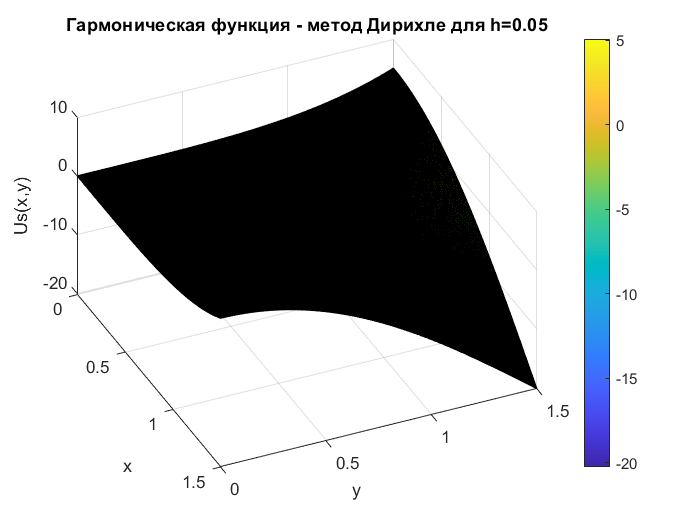

figure
Xs = 0:hs:a;
Ys = 0:hs:b;
surf(Xs,Ys,Us)
title('Гармоническая функция - метод Дирихле для h=0.05')
xlabel('x')
ylabel('y')
zlabel('Us(x,y)')
colorbar

%Поворот в удобную точку обзора
view([65.6 46.8])

#### График аналитического решения:

syms x y
Uan = matlabFunction(x^4-6*x^2*y^2+y^4,'Vars', {x,y});

k = length(Ys);
Ua=zeros(k);
for i = 1:k
    for j = 1:k
        Ua(i,j)=Uan(Xs(i),Ys(j));
    end
end
Ua

Ua =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0016    0.0018    0.0019    0.0021    0.0023    0.0026    0.0028    0.0030    0.0033    0.0036
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0016    0.0018    0.0019    0.0021    0.0023    0.0026    0.0028    0.0030    0.0033    

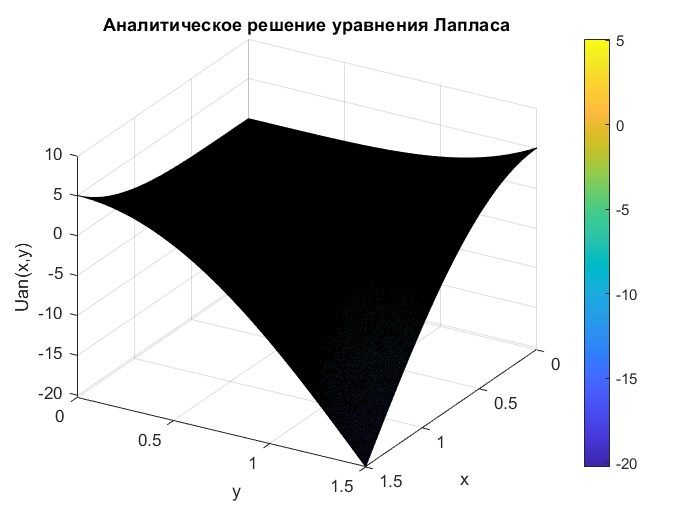

[X,Y]=meshgrid(0:hs:a);
figure;
surf(X,Y,Ua)
title('Аналитическое решение уравнения Лапласа')
xlabel('x')
ylabel('y')
zlabel('Uan(x,y)')
colorbar

%Поворот в удобную точку обзора

xlim([0.00 1.50])
ylim([0.00 1.50])
zlim([-20.3 10.0])
view([120.7 29.4])

#### График разности аналитического и приближённого решений

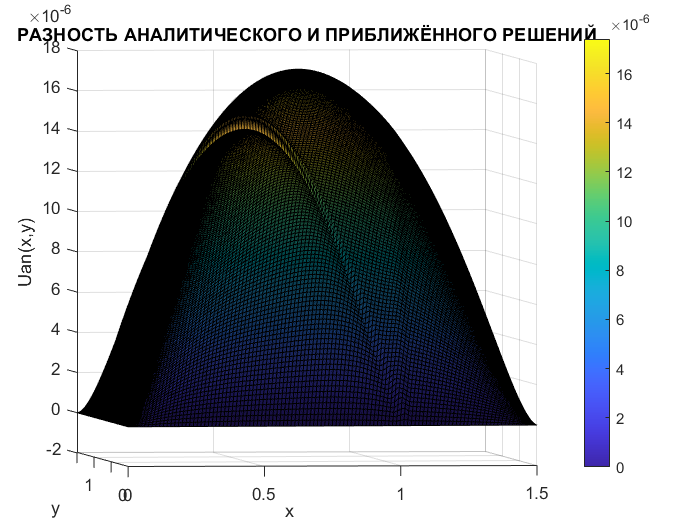

figure;
surf(X,Y,Us-Ua)
title('РАЗНОСТЬ АНАЛИТИЧЕСКОГО И ПРИБЛИЖЁННОГО РЕШЕНИЙ')
xlabel('x')
ylabel('y')
zlabel('Uan(x,y)')
colorbar

function U = dirich(f1,f2,f3,f4,a,b,h,tol,max1)
%Вход   - fl,f2,f3,f4 - граничные функции
%       - a и b - правые крайние точки интервалов [0, a] и [0, b]
%	    - h     - шаг
%	    - tol   - допустимое отклонение
%Выход  - U     - матрица решения

%Инициализация параметров и U
n=fix(a/h)+1;
m=fix(b/h)+1;
ave = (a*(f1(0)+f2(0))+b*(f3(0)+f4(0)))/(2*a+2*b);
U=double(ave*ones(n,m));

%Граничные условия
U(1,1:m)=f3(0:h:(m-1)*h);
U(n,1:m)=f4(0:h:(m-1)*h);
U(1:n,1)=f1(0:h:(n-1)*h);
U(1:n,m)=f2(0:h:(n-1)*h);
U(1,1)=(U(1,2)+U(2,1))/2;
%U(1,m)=(U(1,m-1)+U(2,m))/2;
%U(n,1)=(U(n-1,1)+U(n,2))/2;
%U(n,m)=(U(n-1,m)+U(n,m-1))/2;

%Параметр метода последовательной свехрелаксации 
w=4/(2+sqrt(4-(cos(pi/(n-1))+cos(pi/(m-1)))^2));

%Улучшение приближений и оператор очистки по всей решетке
err=1;
cnt=0;
while ((err>tol)&&(cnt<=max1)) 
    err=0; 
    for j=2:m-1 
        for i=2:n-1
            relx=w*(U(i,j+1)+U(i,j-1)+U(i+1,j)+U(i-1,j)-4*U(i,j))/4;
            U(i,j)=U(i,j)+relx; 
            if (err<=abs(relx)) 
                err=abs(relx); 
            end
        end
    end
    cnt=cnt+1; 
end
if (err<tol)
        disp("required tolerance reached")
 end
if (cnt>max1)
    disp("max iteration number reached")
end
U=transpose(U');
end